match = wildcardPattern + "\";
maa =["N","OA ","(",")",".png"];
data=erase(imdsTest.Files,match);
new_data=erase(data,maa);

new_oa=str2double(string(new_data(1372:end)));
new_n = str2double(string(new_data(1:1371)));

all_OA_label_EEG=gather(all_OA_label_EEG');
all_X_label_EEG=gather(all_X_label_EEG');
all=[all_OA_label_EEG;all_X_label_EEG];

all(new_oa,:)=[];

all_n = gather(all_N_label_EEG');
all_n(new_n,:)=[];

numEx0 = 1701;
numEx1 = 5486;
labels0 = false([numEx0 1]);
labels1 = true ([numEx1 1]);

adasyn_features                 = [all; all_n];
adasyn_labels                   = [labels0  ; labels1  ];
adasyn_beta                     = [];   %let ADASYN choose default
adasyn_kDensity                 = [];   %let ADASYN choose default
adasyn_kSMOTE                   = [];   %let ADASYN choose default
adasyn_featuresAreNormalized    = true;    %false lets ADASYN handle normalization

[adasyn_featuresSyn, adasyn_labelsSyn] = ADASYN(adasyn_features, adasyn_labels, adasyn_beta, adasyn_kDensity, adasyn_kSMOTE, adasyn_featuresAreNormalized);


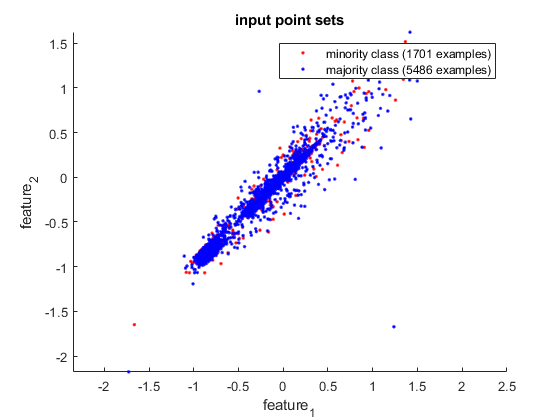



% PLOTTING:

%plot input data:
figure;
hold on;
plot(all(:,1), all(:,2), 'r.');
plot(all_n(:,1),all_n(:,2), 'b.');
title('input point sets');
legend({['minority class (' num2str(numEx0) ' examples)'] ['majority class (' num2str(numEx1) ' examples)']});
xlabel('feature_1');
ylabel('feature_2');
axis('equal');
hold off;

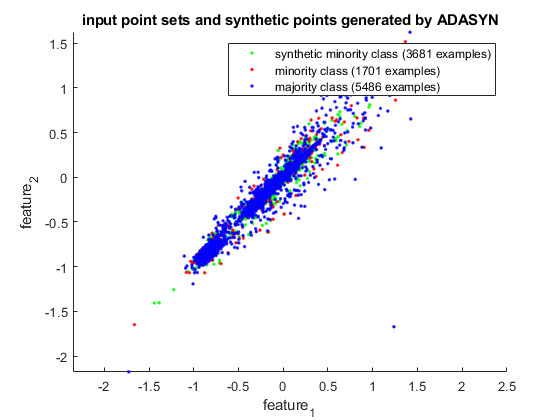


%plot synthesized examples in green:
figure;
hold on;
plot(adasyn_featuresSyn(:,1), adasyn_featuresSyn(:,2), 'g.');
plot(all(:,1), all(:,2), 'r.');
plot(all_n(:,1), all_n(:,2), 'b.');
title('input point sets and synthetic points generated by ADASYN');
legend({['synthetic minority class (' num2str(size(adasyn_featuresSyn,1)) ' examples)'] ['minority class (' num2str(numEx0) ' examples)'] ['majority class (' num2str(numEx1) ' examples)']});
xlabel('feature_1');
ylabel('feature_2');
axis('equal');
hold off;

adasyn_data_oa = [all;adasyn_featuresSyn];